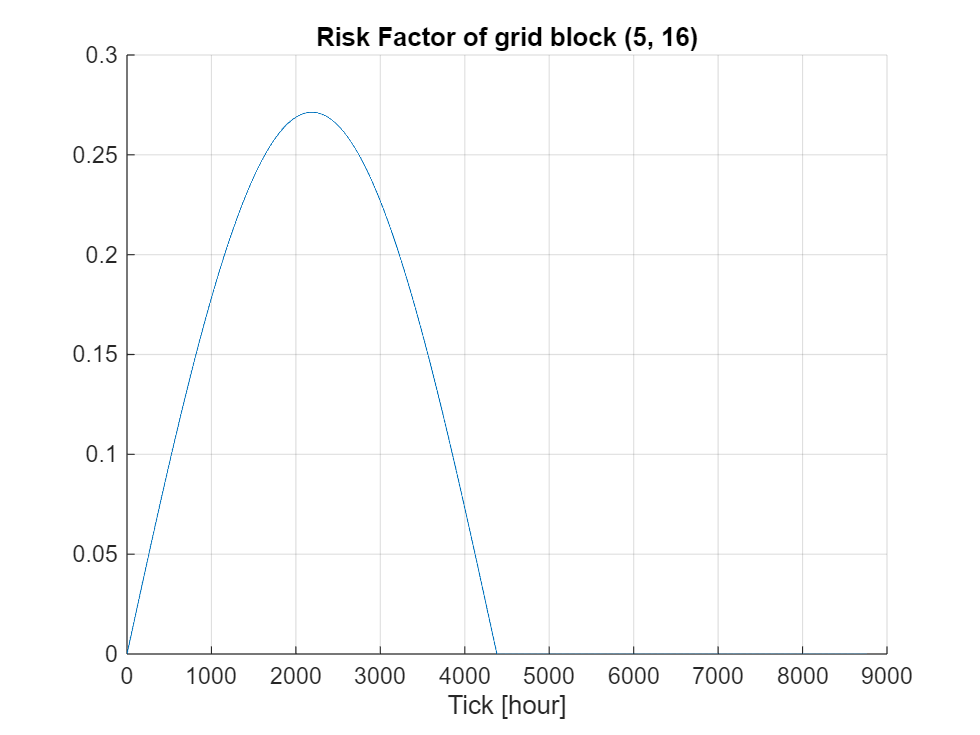


%#ok<*CLALL>

clear all;clc 


gridSettings = gridSettingsClass; 

gridSettings.gridSize = [128, 256]; 

% Let 1 tick be 1 hour. 
gridSettings.ticksPerYear = 365*24; 

gridSettings.restoreGridHealthRate = 1/gridSettings.ticksPerYear; 

gridSettings.restoreGridHealthCost = 1; 

gridSettings.newFireIntensityMax = 1E-1; 
gridSettings.newFireIntensityMean = 0.01; 
gridSettings.newFireIntensityStandardDeviation = 0.01; 

gridSettings.fireIntensityScaler = 1; 
gridSettings.peakIntensityHealthMin = 0.5; 
gridSettings.peakIntensityHealthMax = 0.7; 
gridSettings.peakIntensityHealth_mean = 0.6; 
gridSettings.peakIntensityHealth_standardDeviation = 0.02; 

simGrid = gridClass(gridSettings); 

% Take a peek at grid block (5, 16): 
tspan = 1 : simGrid.ticksPerYear; 
% tspan = 1 : 2; 
riskFactorPeekaboo = zeros(length(tspan), 1); 
tic; 
for tick = tspan
    simGrid.updateGrid(); 
    riskFactorPeekaboo(tick) = simGrid.riskFactor(5, 16); 
end
clf; 
hold on; 
grid on; 
plot(tspan, riskFactorPeekaboo); 
xlabel("Tick [hour]"); 
title("Risk Factor of grid block (5, 16)"); 
hold off; 

toc; 

Elapsed time is 10.855414 seconds.
